L =
 
     s + 1
  -----------
  s^2 + s - 6
 
Continuous-time transfer function.



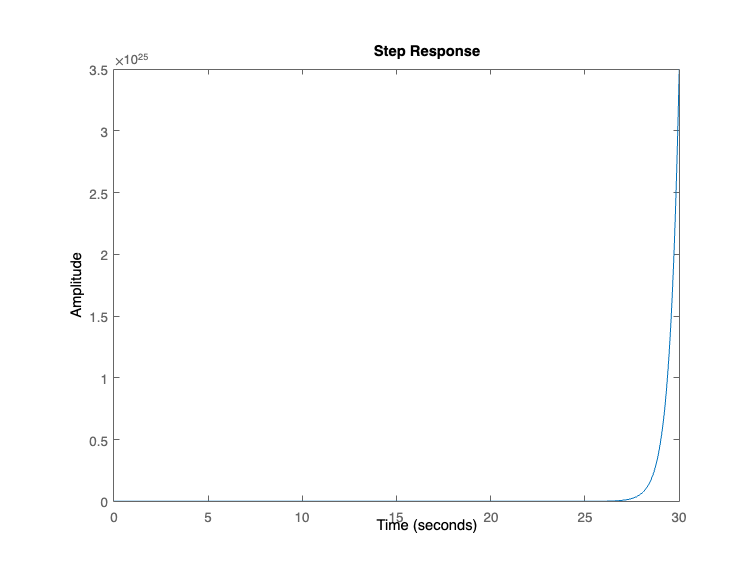

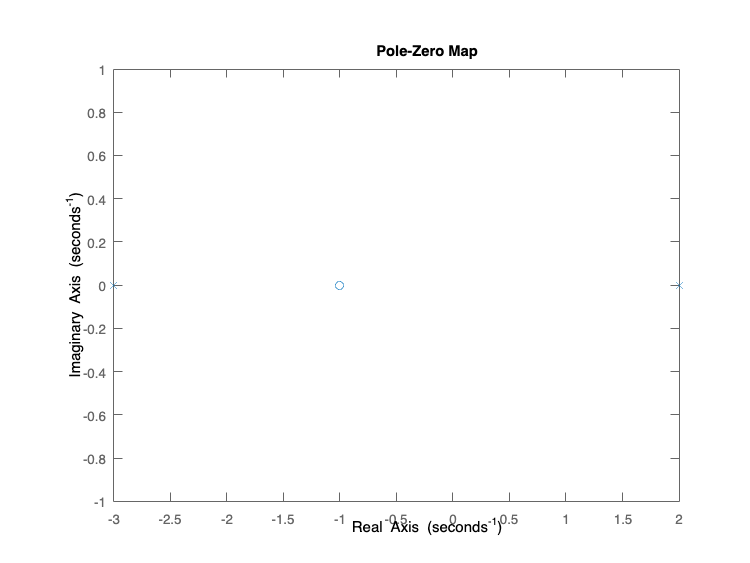

T =
 
   6 s + 6
  ---------
  s^2 + 7 s
 
Continuous-time transfer function.



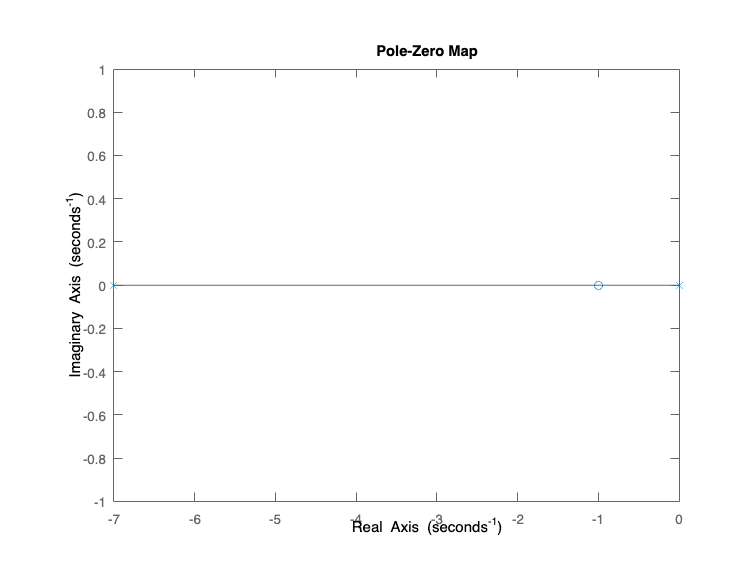

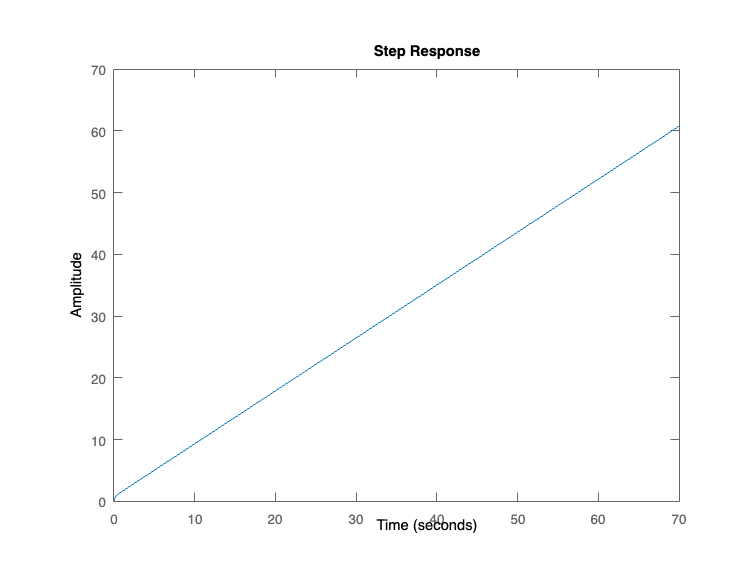

T =
 
     6.1 s + 6.1
  -----------------
  s^2 + 7.1 s + 0.1
 
Continuous-time transfer function.



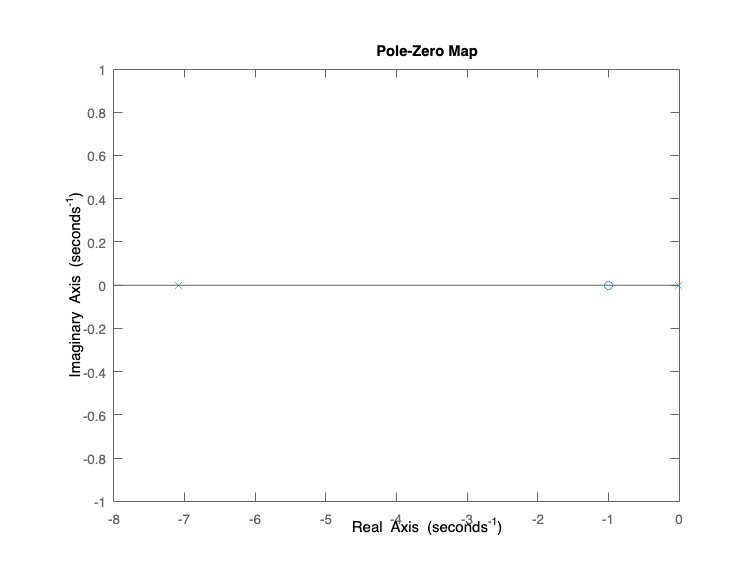

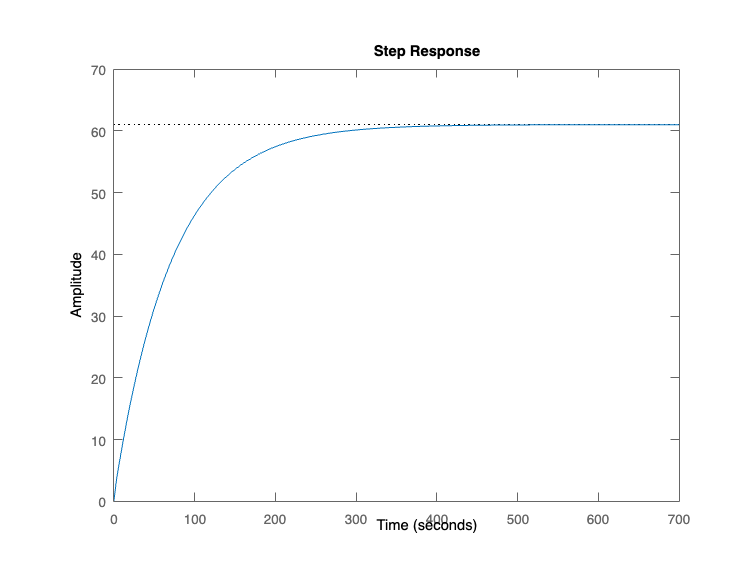

T =
 
     5.9 s + 5.9
  -----------------
  s^2 + 6.9 s - 0.1
 
Continuous-time transfer function.



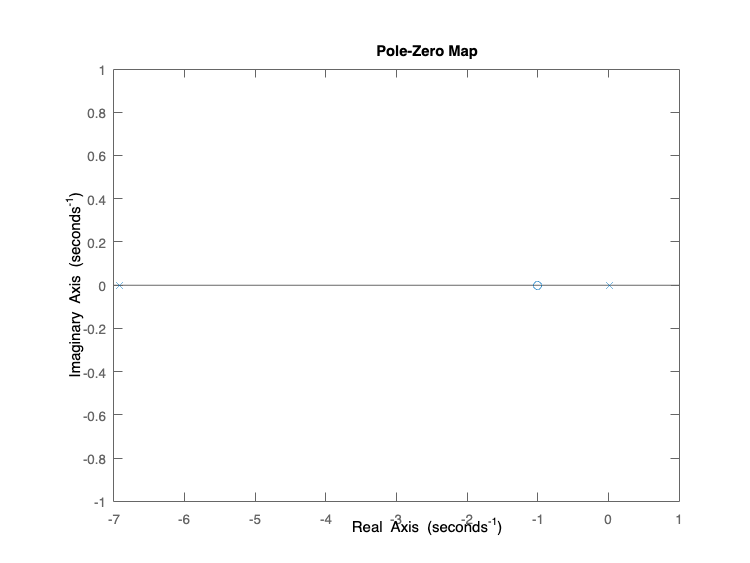

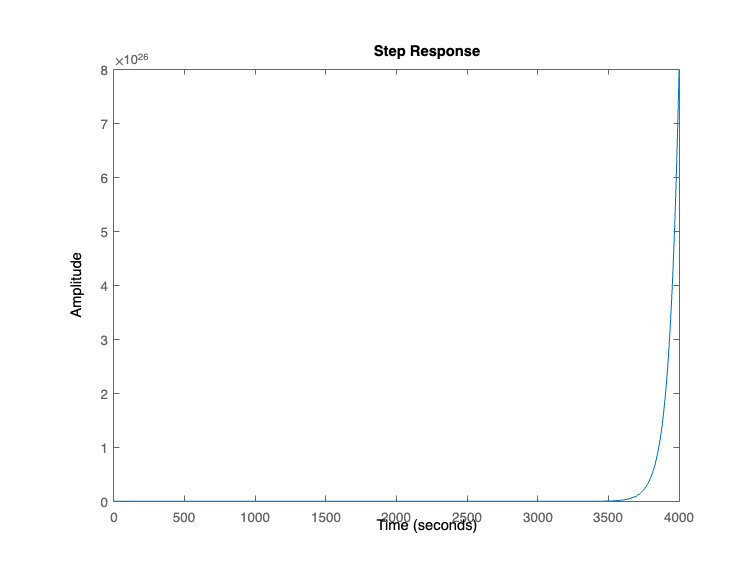

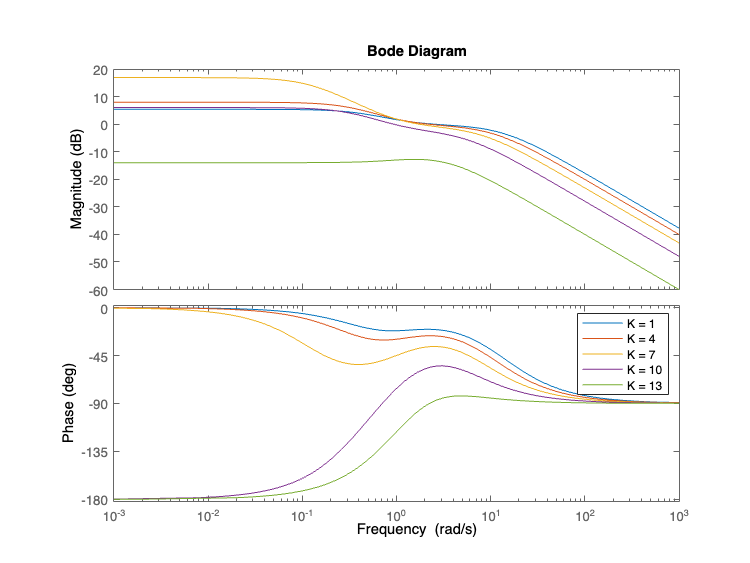

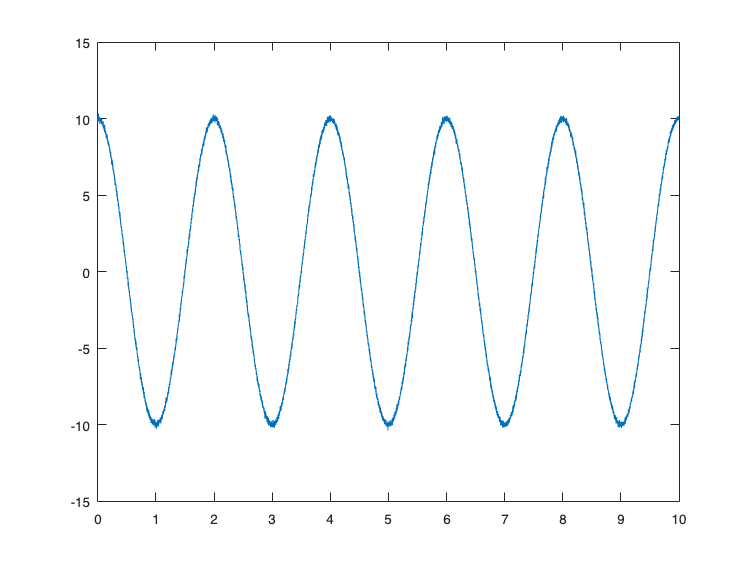

a = 0.4700

HzFIR =
 
  0.53 z + 0.47
  -------------
        z
 
Sample time: unspecified
Discrete-time transfer function.



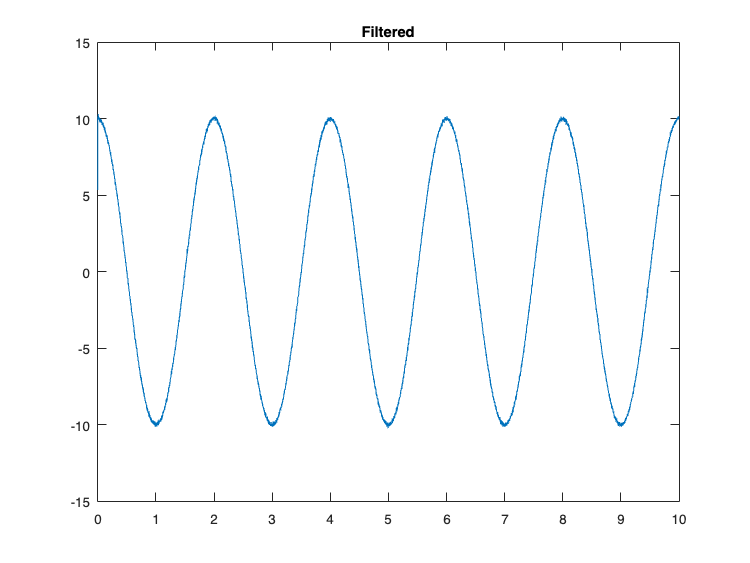

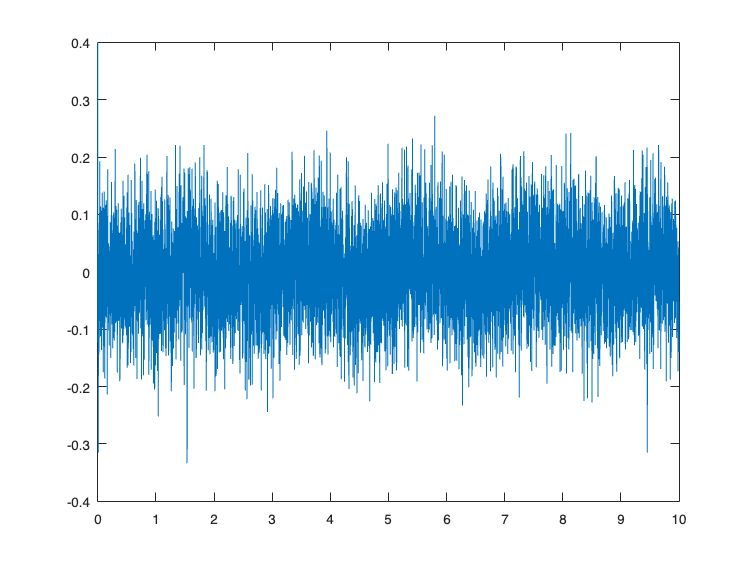

a = 0.7100

HzIIR =
 
    0.29
  --------
  z - 0.71
 
Sample time: unspecified
Discrete-time transfer function.



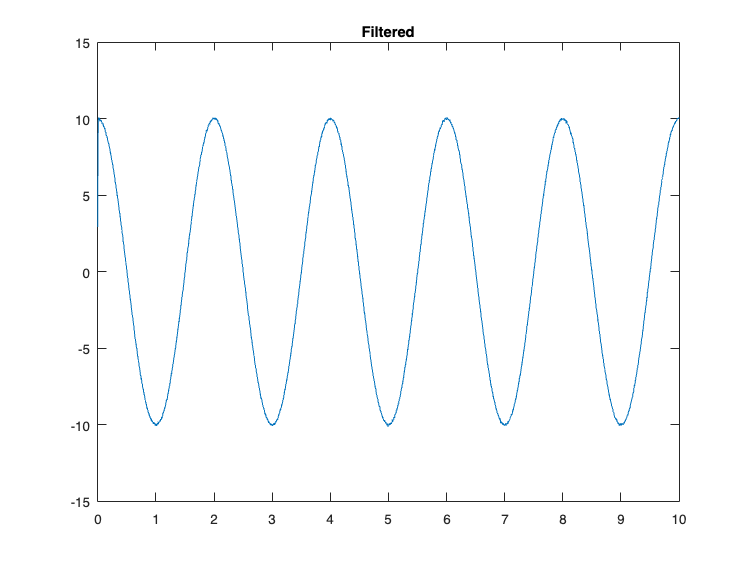

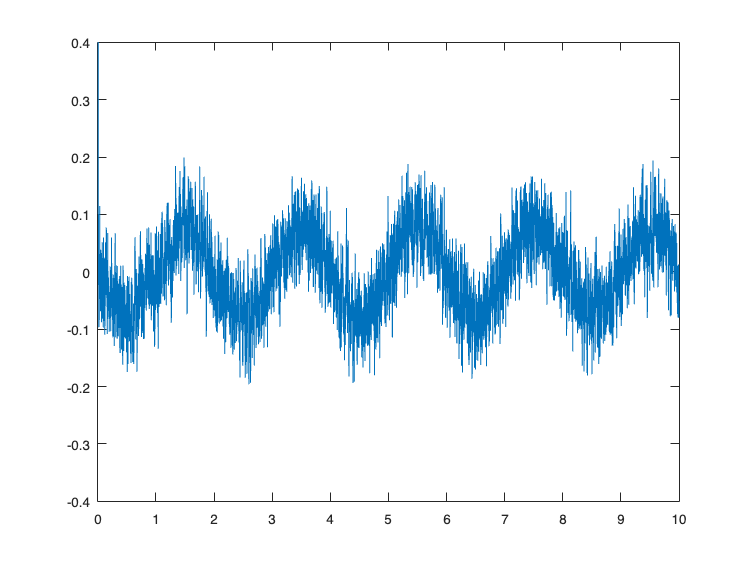

a = 1.0010

HzIIR =
 
   -0.001
  ---------
  z - 1.001
 
Sample time: unspecified
Discrete-time transfer function.



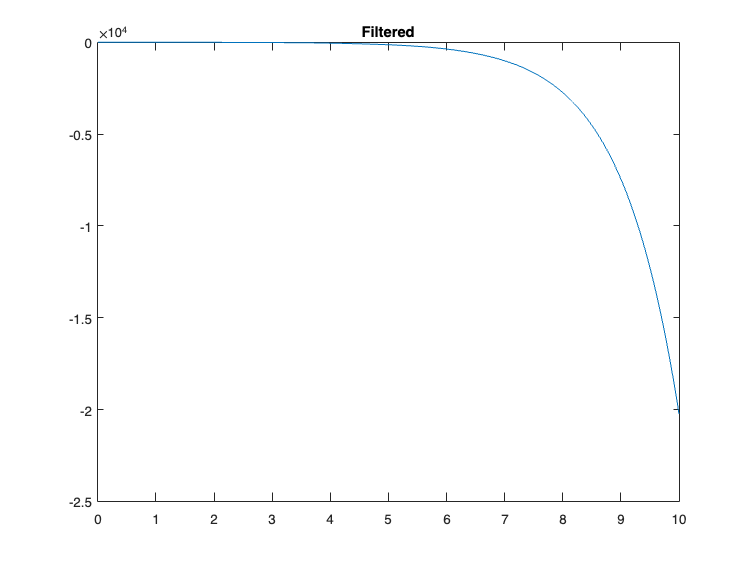

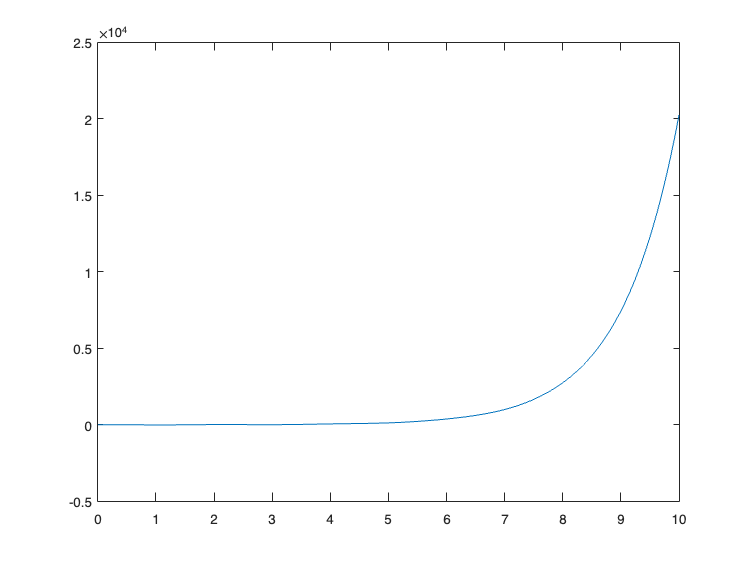

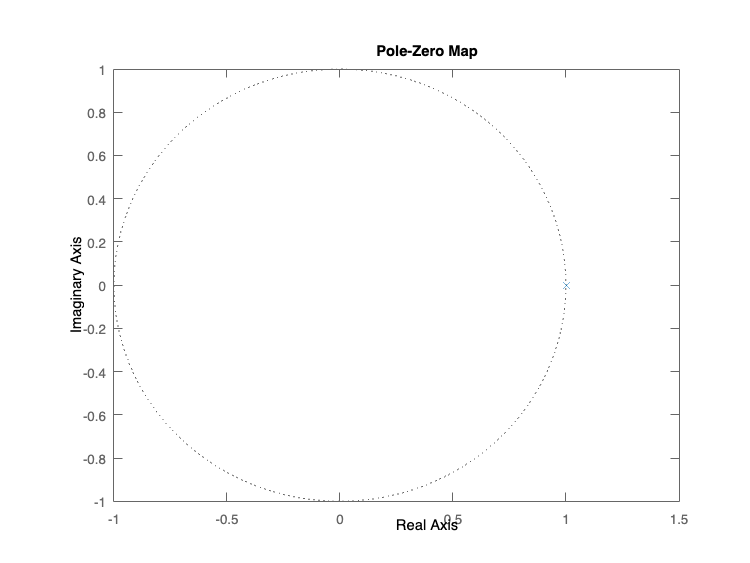

[x, Fs] = audioread('Noised_Piano.wav', [1 Inf], 'double');

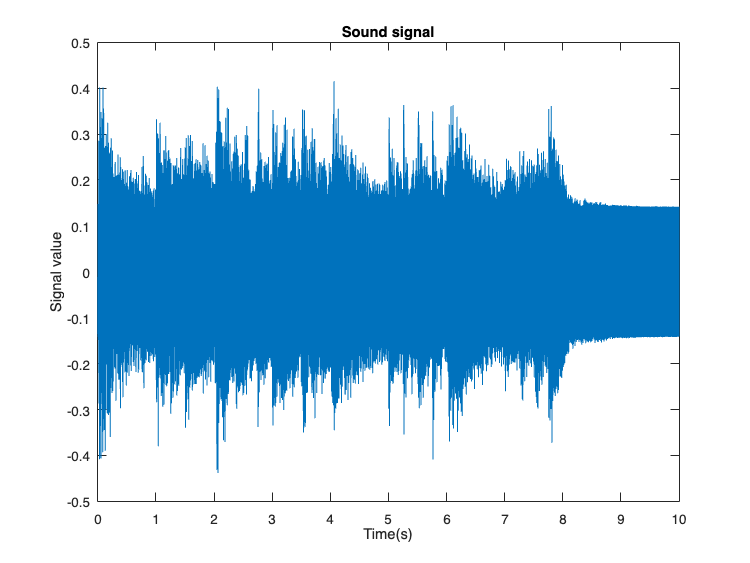

N = length(x);
t = (0:N-1) / Fs;
figure
plot(t, x);
xlim([0,10]);
xlabel('Time(s)');
ylabel('Signal value');
title(["Sound signal"]);

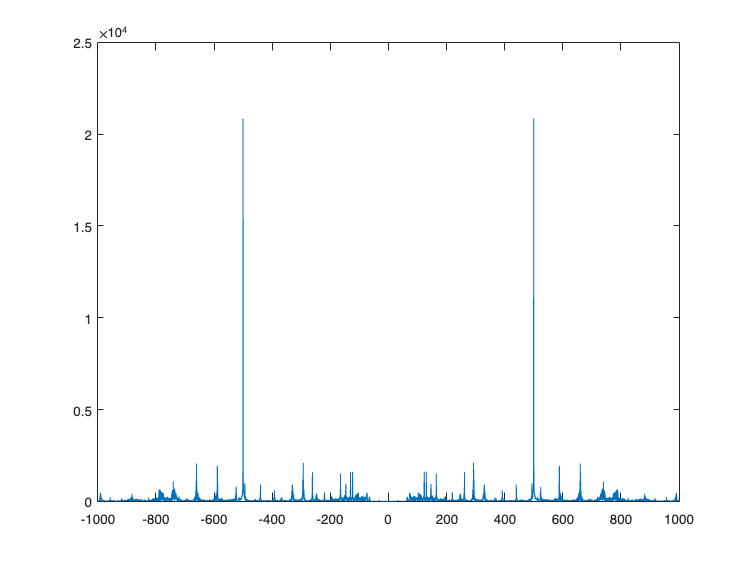

X = fft(x); 
Y = fftshift(X);
L = length(X);
f = Fs*((-L/2):(L/2)-1)/L;
figure
plot(f,fftshift(abs(X)))
xlim([-1000 1000])

Here on FFT plot we have a lot of signal on 500Hz frequency, on normal sound signal we have signal from all of frequences and here we have a lot of signal around 500Hz.

its soppused to be frequency of noise

fn = 500Hz

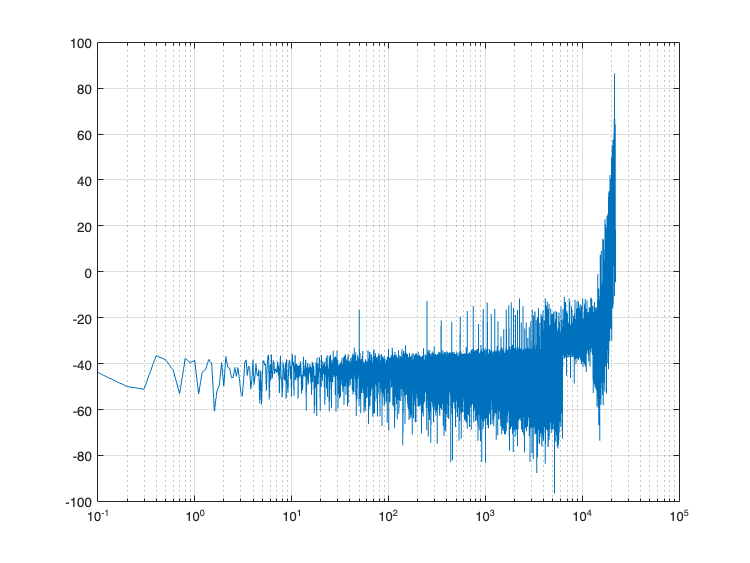

figure
semilogx(f,20*log10(abs(X)));
grid on

No we cant, we cant find the noise frequency from this figure and need to do frequency analysis.

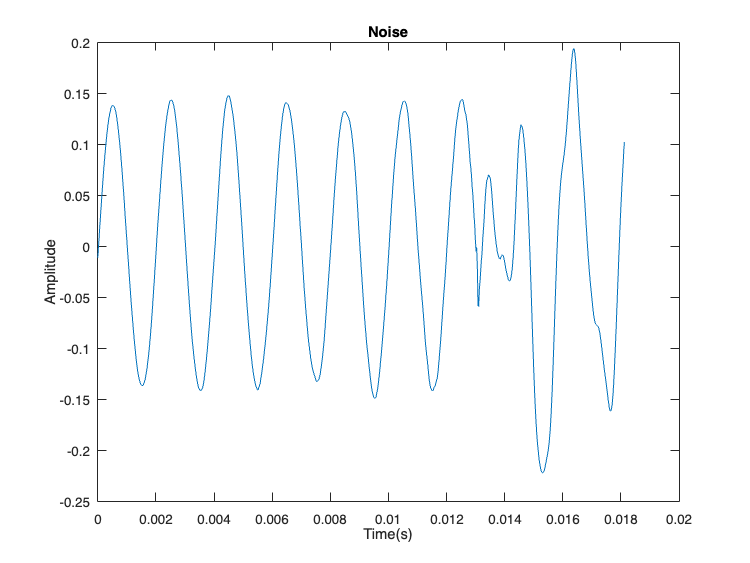

N = 800;
figure
plot(t(1:N),x(1:N))
xlabel('Time(s)');
ylabel('Amplitude');
title(["Noise"]);

N = 90

N = 90

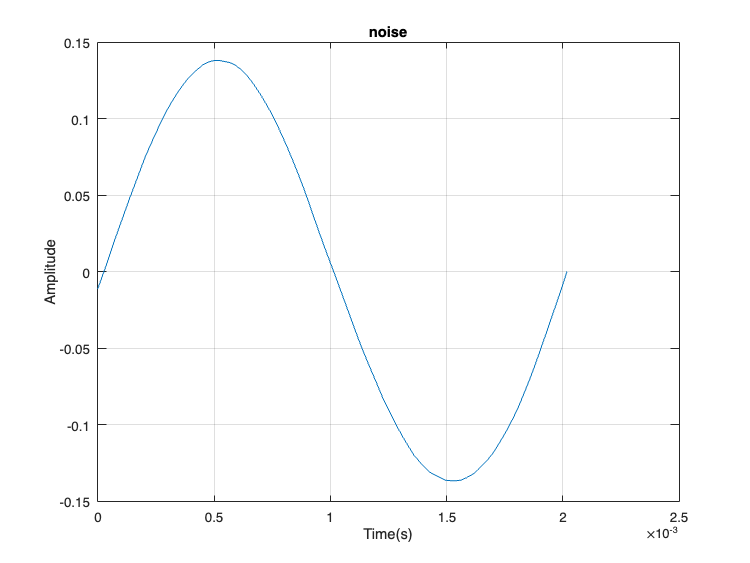

figure
plot(t(1:N),x(1:N))
grid on
xlabel('Time(s)');
ylabel('Amplitude');
title(["noise"]);

Here we can check noise frequency is `around` 500Hz.

With figure window the exact fn is around 500.1Hz.

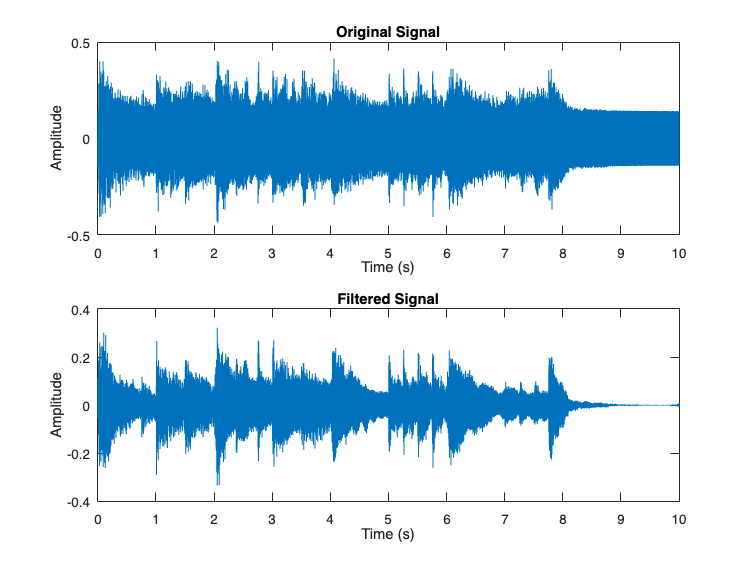

fn = 500.074;
Z = Y;
Y(logical(((f<=-fn+100) & (f >= -fn-100)) | ((f<=fn+100) & (f>= fn-100)))) = 0;
DenoisedSIG1 = ifft(ifftshift(Y));
figure;
subplot(2,1,1);
plot(t,x);
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 10])
title('Original Signal');

subplot(2,1,2);
plot(t,DenoisedSIG1);
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 10])
title('Filtered Signal');

In this filter we denosie with band filter and its not bad!

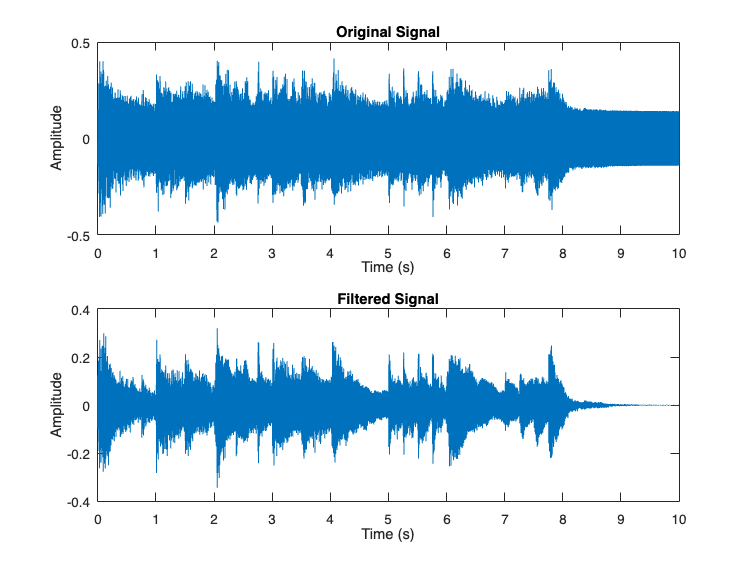


audiowrite("Piano_Ideal.wav",DenoisedSIG1,Fs)

fs = 44100; 
f0 = 500.074; 
Q = 7; 
wo = f0/(fs/2); 
bw = wo/Q; 
[b,a] = iirnotch(wo,bw);
DenoisedSIG2 = filter(b,a,x);

figure
subplot(2,1,1);
plot(t,x);
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 10])
title('Original Signal');

subplot(2,1,2);
plot(t,DenoisedSIG2);
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 10])
title('Filtered Signal');

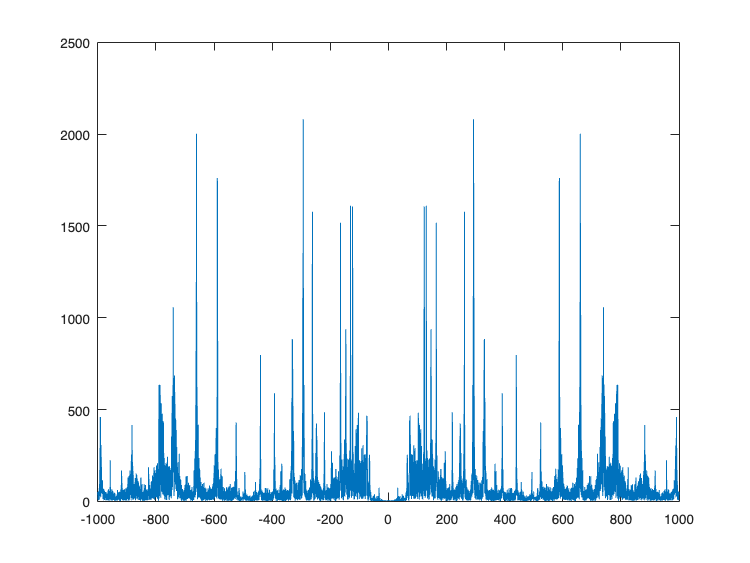

X = fft(DenoisedSIG2);
Y = fftshift(X);
L = length(X);
f = Fs*((-L/2):(L/2)-1)/L;
figure
plot(f,fftshift(abs(X)))
xlim([-1000 1000])

audiowrite("Piano_notch.wav",DenoisedSIG2,Fs)

NEXT MUSIC FILE:

Following code is copy of previous part..

.

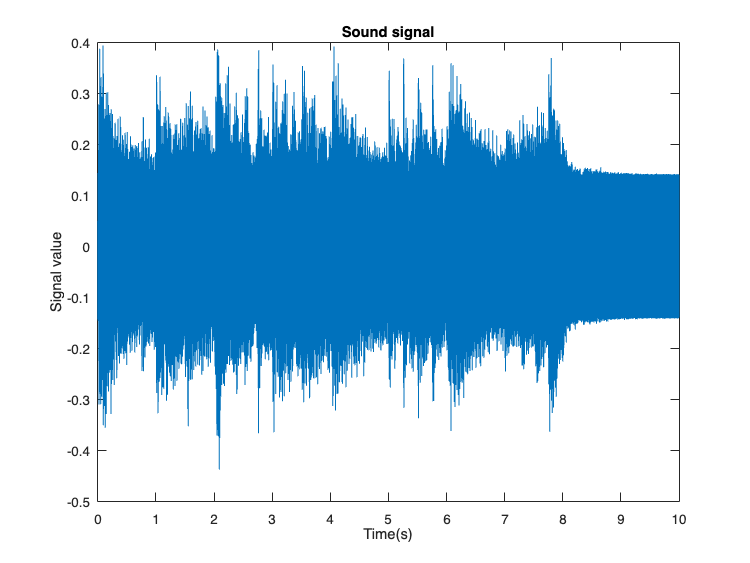

[x, Fs] = audioread('Noised_Piano_2.wav', [1 Inf], 'double');
N = length(x);
t = (0:N-1) / Fs;
figure
plot(t, x);
xlim([0,10]);
xlabel('Time(s)');
ylabel('Signal value');
title(["Sound signal"]);

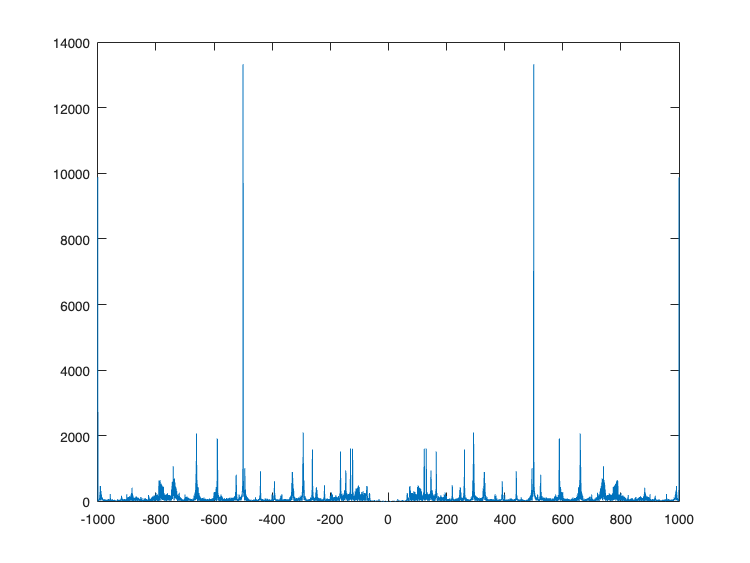

X = fft(x); 
Y = fftshift(X);
L = length(X);
f = Fs*((-L/2):(L/2)-1)/L;
figure
plot(f,fftshift(abs(X)))
xlim([-1000 1000])

Here on FFT plot we have a lot of signal on 500Hz frequency, on normal sound signal we have signal from all of frequences and here we have a lot of signal around 500Hz.

its soppused to be frequency of noise

fn = 500Hz

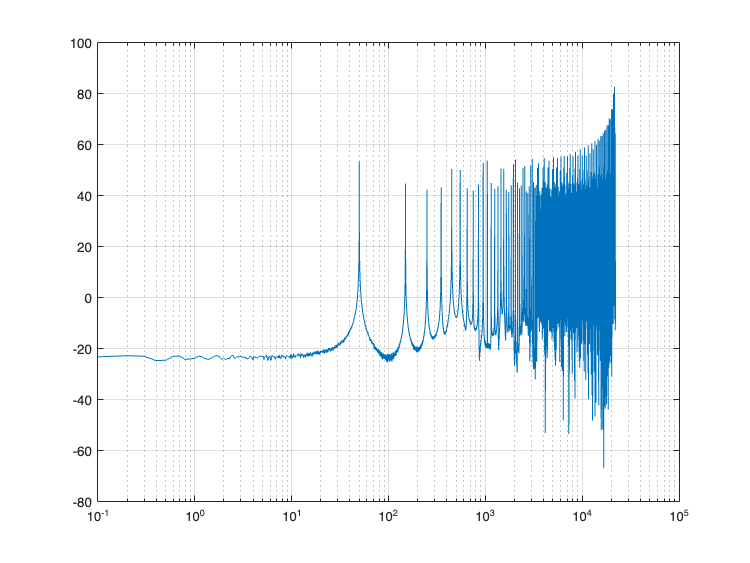

figure
semilogx(f,20*log10(abs(X)));
grid on

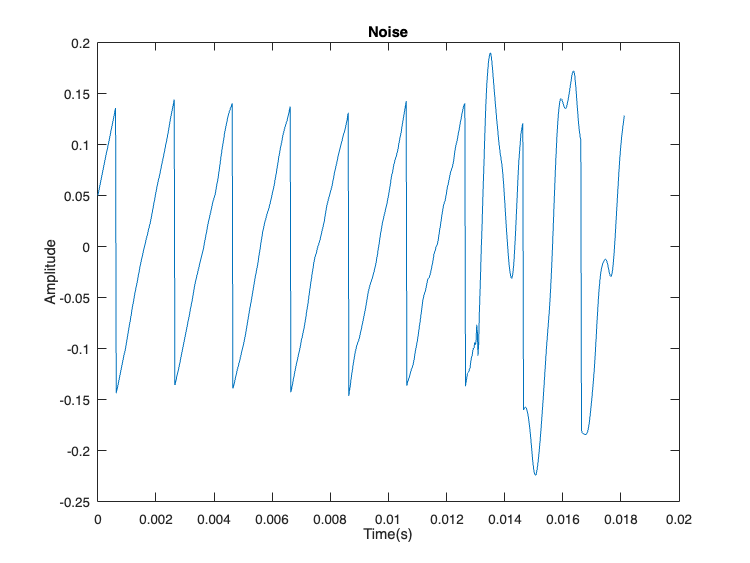

N = 800;
figure
plot(t(1:N),x(1:N))
xlabel('Time(s)');
ylabel('Amplitude');
title(["Noise"]);

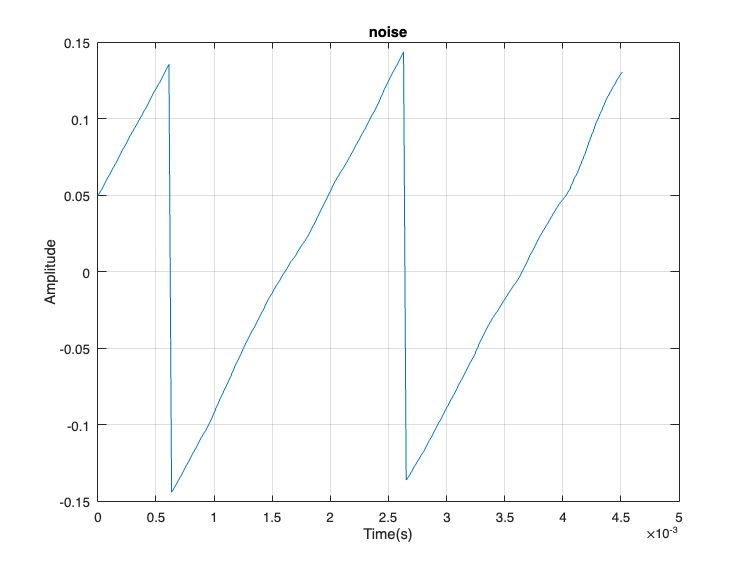

N = 200;
figure
plot(t(1:N),x(1:N))
grid on
xlabel('Time(s)');
ylabel('Amplitude');
title(["noise"]);

Here we can check noise frequency is `around` 500Hz.

With figure window the exact fn is around 500.1Hz.

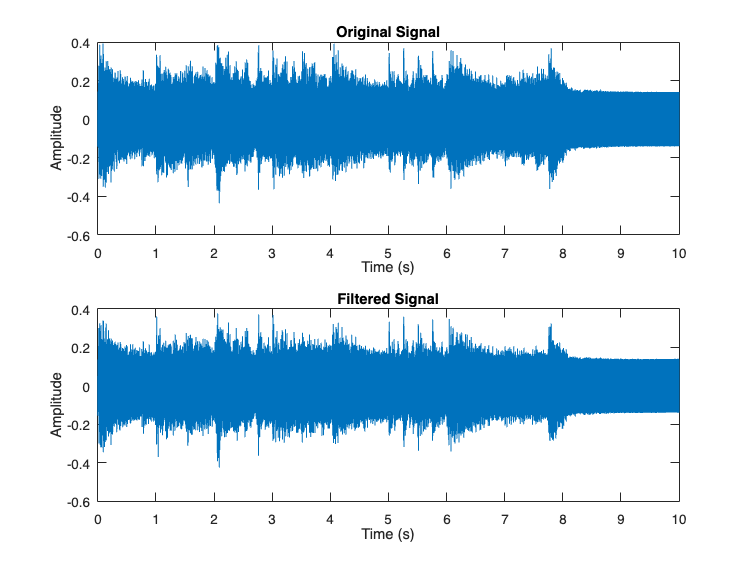

fn = 500.074;
Z = Y;
Y(logical(((f<=-fn+100) & (f >= -fn-100)) | ((f<=fn+100) & (f>= fn-100)))) = 0;
DenoisedSIG1 = ifft(ifftshift(Y));
figure;
subplot(2,1,1);
plot(t,x);
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 10])
title('Original Signal');

subplot(2,1,2);
plot(t,DenoisedSIG1);
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 10])
title('Filtered Signal');

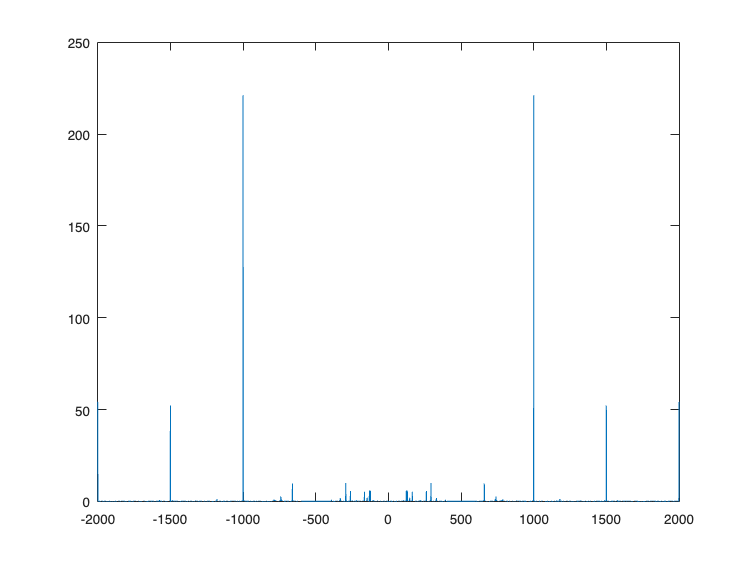

figure
plot(f,abs(Y).^2/L)
xlim([-2000 2000])

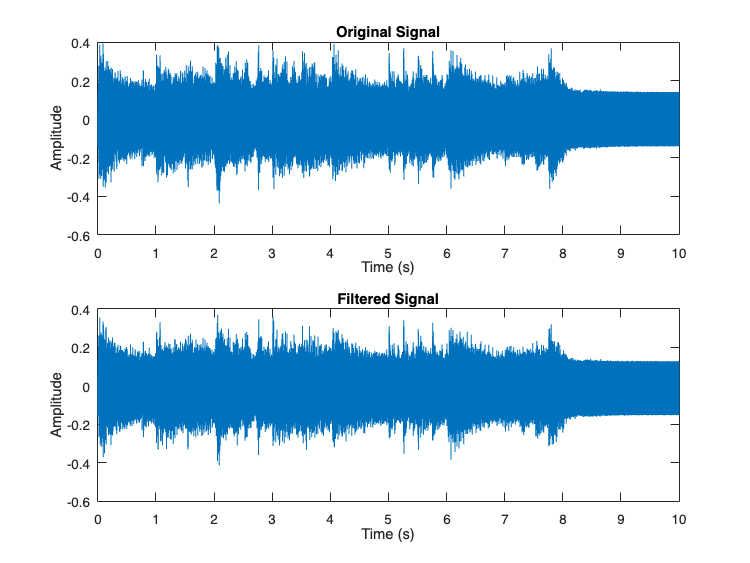


audiowrite("Piano_Ideal_2.wav",DenoisedSIG1,Fs)

fs = 44100; 
f0 = 500.074; 
Q = 5;
wo = f0/(fs/2);
bw = wo/Q; 
[b,a] = iirnotch(wo,bw);
DenoisedSIG2 = filter(b,a,x);

figure;
subplot(2,1,1);
plot(t,x);
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 10])
title('Original Signal');

subplot(2,1,2);
plot(t,DenoisedSIG2);
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 10])
title('Filtered Signal');

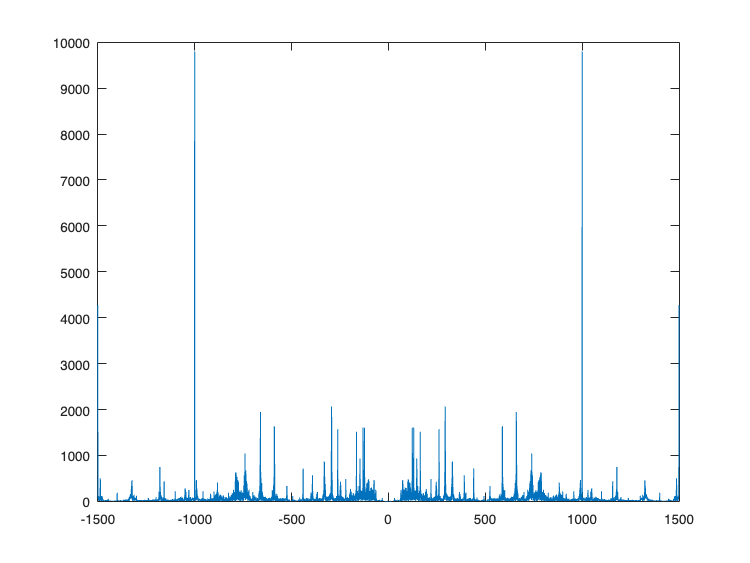

X = fft(DenoisedSIG2); 
Y = fftshift(X);
L = length(X);
f = Fs*((-L/2):(L/2)-1)/L;
figure
plot(f,fftshift(abs(X)))
xlim([-1500 1500])

I filter this signal with band and notch to remove first harmonic but we still hear noise and it sounds normal for triangular noise

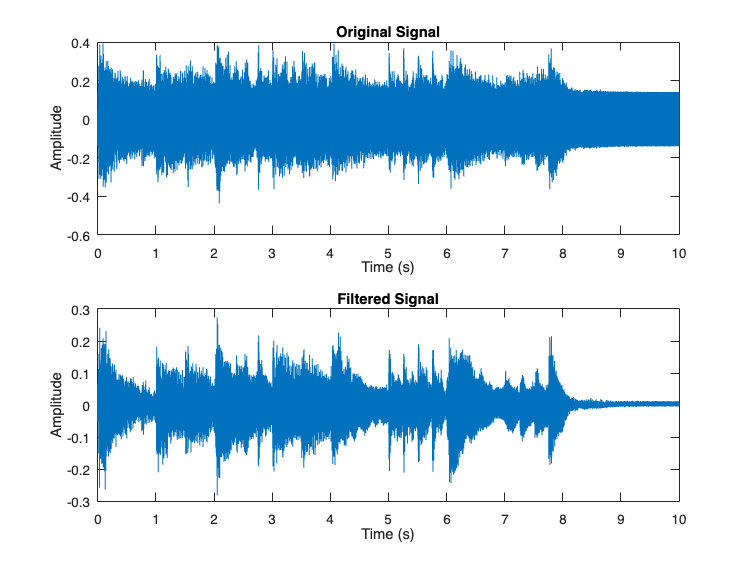

audiowrite("Piano_notch_2.wav",DenoisedSIG2,Fs)

DenoisedSIG2_50 = filter(b,a,DenoisedSIG2);
for i = 1:44
    [b, a] = iirnotch(i * wo,i* bw);
    DenoisedSIG2_50 = filter(b, a, DenoisedSIG2_50);
end

figure;
subplot(2,1,1);
plot(t,x);
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 10])
title('Original Signal');

subplot(2,1,2);
plot(t,DenoisedSIG2_50);
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 10])
title('Filtered Signal');

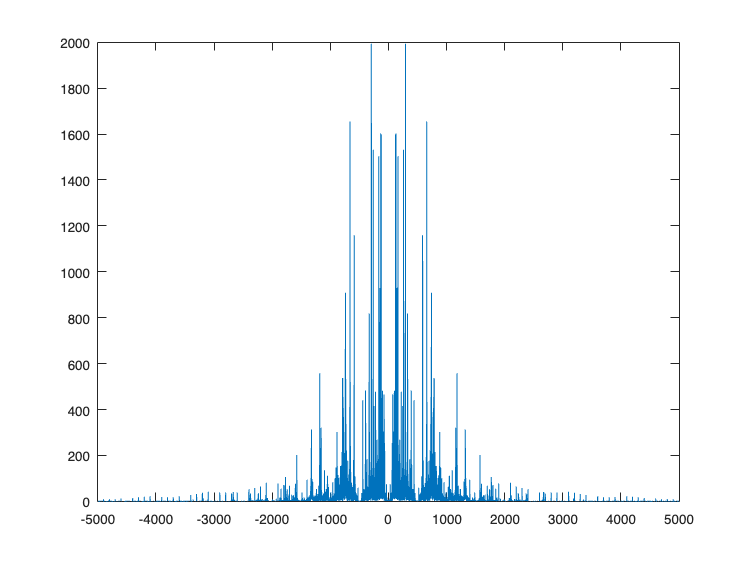

X = fft(DenoisedSIG2_50);
Y = fftshift(X);
L = length(X);
f = Fs*((-L/2):(L/2)-1)/L;
figure
plot(f,fftshift(abs(X)))
xlim([-5000 5000])

We cant remove upto 50 harmonic.

44th harmonic is the lastone we can remove and its good right now.

audiowrite("Piano_50.wav",DenoisedSIG2_50,Fs)

For the last part, almost everything is on the upper frequecy is noise and when we remove the noises, our hearing focus is on low frequences and when we listen to the music we hear the low frequences noise...